clear
clc
%%
% load('small_suqsireal_network.mat')
% load('large_suqsireal_network.mat')

% load('inital_simulation_1000cells.mat')

% load('inital_simulation_smallING.mat')
% load('400ING_network')

load('inital_simulation_INGpacingIEnetwork3.mat')
global T_MAX step 
T_MAX             = 1000;
step              = 0.1;
tspan             = 0:step:T_MAX; 
clear optoStimulus_in
% figure; plot(h);


% 光刺激序列
% 经过测试，很难找到像5mW/mm2，10/50ms，20Hz脉冲序列这样，能实现1个光脉冲 = 1个spiking的一组理想参数（已解，方程函数中新增电导密度参数）
sDelay                          = 200;                         % 光刺激起始时间，default 200
sStart                          = 200;                         % 光刺激序列开始时间，Opto-stimulus start time (ms) default 200
sEnd                            = T_MAX;                       % 光刺激序列结束时间，Opto-stimulus end time (ms) default 800
pWidth                          = 3;                           % 光刺激脉宽pulse width (ms) - if there is no optical stimulation, make pWidth to 0
pPeriod                         = 25;                          % 光刺激序列周期pulse period (ms)
numPulses                       = (sEnd-sStart)/pPeriod;       % 光刺激序列的数量number of stimulus pulses

Optofrequency                   = 1000/pPeriod

Optofrequency = 40

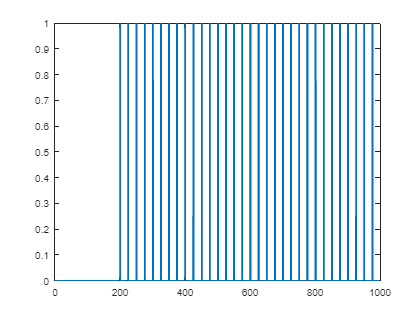


% Create an optical pulse train
optoStimulus(1:length(tspan))   = 0; 
repetition(1:pPeriod/0.1)      = 0; 
repetition(1:pWidth/0.1)       = 1; 

for i = 1:numPulses 
    startPoint = (sDelay/0.1) + ((i-1) * (pPeriod/0.1)); 
    optoStimulus(startPoint+1:startPoint+length(repetition)) = repetition(1:length(repetition));
end

% optoStimulus1                   = optoStimulus';
optoStimulus_in                 = optoStimulus';     
figure;
plot(tspan,optoStimulus_in);                           % 由此生成光刺激波形，绘制光刺激波形图


optoStimulusMatrix(find(type_of_neuron == 2))  = 1;
optoStimulusMatrix(find(type_of_neuron == 1))  = 0;

v_initial = -ones(1,n); 
v_initial = v_initial';

for i = 1:n
    % v_initial(i) = (66+20.*(rand(1,1)-0.2))*v_initial(i); 
    v_initial(i) = (66+20.*(rand(1,1)-0.5))*v_initial(i);
end 

% v_initial = 66.*v_initial;

initial   = initial(n+1:end);
initial   = [v_initial;initial];

irradiance= 0.5;
% irradiance= 0.0001;
% irradiance= 0.06;
% irradiance= 0.1; % for pyramidal cells

opts = odeset('RelTol',1e-6,'AbsTol',1e-6);

% elecStimulus_in(1)            = 0.5;
% elecStimulus_in(2)            = 1;
% elecStimulus_in(3)            = 1.5;

elecStimulus_in = zeros(600,1);
% elecStimulus_in(find(type_of_neuron == 1)) = 1.25;
elecStimulus_in(find(type_of_neuron == 1)) = 0.7.*(rand(400,1)-0.5)+1;
% elecStimulus_in(find(type_of_neuron == 2)) = 0.0025.*(rand(200,1)-0.5)+0.05;
% elecStimulus_in(find(type_of_neuron == 1)) = zeros(100,1)+0.4;

% elecStimulus_in(find(type_of_neuron == 1)) = 1.5.*(rand(100,1)-0.5)+8;
% elecStimulus_in(find(type_of_neuron == 2)) = 0.26.*(rand(200,1)-0.5)+1.3;

% elecStimulus_in = zeros(300,1);

% for k = 1:n
%     elecStimulus_in(k) = - 1*rand(1,1)*rand(1,1) + 2*rand(1,1); 
% end

% elecStimulus_in = zeros(n,1);




tic                                       
[t, resultMatrix1] = ode23(@(t,x) EI_network1117(t,x,tspan,elecStimulus_in,elecStimulusMatrix, sstoch, noiseValue, ...
    optoStimulus_in,optoStimulusMatrix,irradiance,ConnectMatrix,type_of_neuron,n,...
    e_to_e_indices, e_to_i_indices,i_to_e_indices,i_to_i_indices),tspan,initial);
toc

历时 1213.530923 秒。



% returnMatrix = EI_network1117(t, y, tspan, elecStimulus,elecStimulusMatrix, sstoch, noiseValue, ...
%     optoStimulus, optoStimulusMatrix,irradiance, ConnectMatrix, type_of_neuron, n, ...
%     e_to_e_indices,e_to_i_indices,i_to_e_indices,i_to_i_indices)

% [t, resultMatrix] = ode23(@(t,x) EI_network_opto0717(t,x,tspan,elecStimulus,elecStimulusMatrix, ...
%     optoStimulus,optoStimulusMatrix,irradiance,ConnectMatrix,synapticMatrix,n,sstoch, noiseValue),tspan,initial);


%% 以下为测试数据使用的代码，可以根据具体情况删改使用

% Data Analysis and Figure Plotting 

timeStep = 0.1;
time_interval = [1 T_MAX];
Vmembrane = resultMatrix1(:,1:n);


## 绘制rasterplots

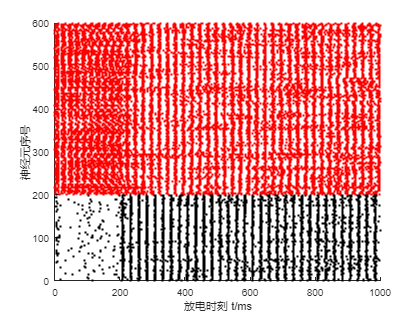


% tic
% % draw_rasterplots(Vmembrane, n,time_interval,timeStep,tspan)  % threshold should be adjustable
% spikedata = rasterplots_0116(Vmembrane,tspan,type_of_neuron);
% toc

tic
% draw_rasterplots(Vmembrane, n,time_interval,timeStep,tspan)  % threshold should be adjustable
spikedata1 = rasterplots_rearrange(Vmembrane,tspan,type_of_neuron);

toc

历时 3.371182 秒。



spikedata1_int = spikedata1(find(spikedata1(:,3)==2),:);
spikedata1_py = spikedata1(find(spikedata1(:,3)==1),:);

% [syn1] = synchronization_new(Vmembrane,n,time_interval,timeStep) 


## 绘制神经元膜电位图

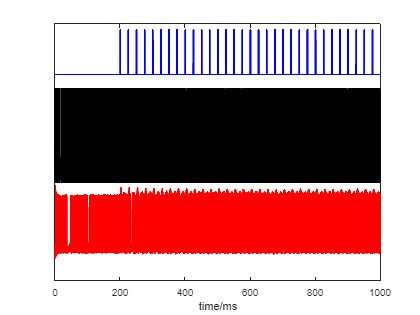


% cellnumber1 = 1
% figure;
% plot(tspan,Vmembrane(:,cellnumber1)); 
% cellnumber2 = 79
% figure;
% plot(tspan,Vmembrane(:,cellnumber2)); 
% cellnumber3 = 400
% figure;
% plot(tspan,Vmembrane(:,cellnumber3)); 
% cellnumber = 25
% figure;
% plot(tspan,Vmembrane(:,25)); 

figure;
for i = find(type_of_neuron == 1)
    plot(tspan,Vmembrane(:,i),'black');
    hold on
end
% plot(tspan,(optoStimulus_in.*70-80),'cyan');

for i = find(type_of_neuron == 2)
    plot(tspan,Vmembrane(:,i)-140,'red');
    hold on
end
% plot(tspan,(optoStimulus_in.*70-80),'cyan');
plot(tspan,(optoStimulus_in.*70+70),'blue');
xlabel('time/ms')
% axis([0 1000 -2950 150])
set(gca,'YTick',[])

## 绘制带光刺激波形的放电图


% view_time_span = [0 1000];
% 
% figure;
% subplot(2,2,1);
% plot(tspan,Vmembrane(:,1),'black');
% hold on
% plot(tspan,Vmembrane(:,10),'red');
% hold on
% plot(tspan,(optoStimulus_in.*100-80),'cyan');
% axis([view_time_span -100 50])
% title('e to i connections')
% 
% % legend('受激神经元放电序列','光刺激序列');
% subplot(2,2,2);
% plot(tspan,Vmembrane(:,1),'black');
% hold on
% plot(tspan,Vmembrane(:,15),'red');
% hold on
% plot(tspan,(optoStimulus_in.*100-80),'cyan');
% axis([view_time_span -100 50])
% title('e to e connections')
% 
% subplot(2,2,3);
% plot(tspan,Vmembrane(:,12),'black');
% hold on
% plot(tspan,Vmembrane(:,15),'red');
% hold on
% plot(tspan,(optoStimulus_in.*100-80),'cyan');
% axis([view_time_span -100 50])
% title('i to e connections')·
% 
% subplot(2,2,4);
% plot(tspan,Vmembrane(:,20),'black');
% hold on
% plot(tspan,Vmembrane(:,30),'red');
% hold on
% plot(tspan,(optoStimulus_in.*100-80),'cyan');
% axis([view_time_span -100 50])
% title('i to i connections')

view_time_span = [0 1000];

% figure;
% cellord = 110;
% plot(tspan,Vmembrane(:,cellord),'black');
% hold on
% plot(tspan,(sstoch(:,cellord).*100-80),'cyan');
% axis([view_time_span -100 50])
% hold off
% title('i-response to stimulus')

figure;
plot(tspan,Vmembrane(:,1),'black'); 
hold on
for i = 2:20
    plot(tspan,Vmembrane(:,i)-140*(i-1),'black');
end
% plot(tspan,(optoStimulus_in.*70-80),'cyan');
plot(tspan,(optoStimulus_in.*70+70-2950),'blue');
xlabel('time/ms')
axis([0 1000 -2950 150])
set(gca,'YTick',[])

% figure;
% subplot(3,1,1)
% plot(tspan,Vmembrane(:,1),'red');
% hold on
% plot(tspan,(optoStimulus_in.*100-80),'cyan');
% axis([view_time_span -100 50])
% hold off
% title('i-response to stimulus')
% subplot(3,1,2)
% plot(tspan,Vmembrane(:,2),'black');
% title('modulated e-response')
% subplot(3,1,3)
% plot(tspan,Vmembrane(:,3),'black');
% title('modulated e-response')

% figure;
% subplot(3,1,1)
% plot(tspan,Vmembrane(:,4),'red');
% axis([view_time_span -100 50])
% title('i-response to stimulus')
% subplot(3,1,2)
% plot(tspan,Vmembrane(:,5),'black');
% title('modulated e-response')
% subplot(3,1,3)
% plot(tspan,Vmembrane(:,6),'black');
% title('modulated e-response')

% figure;
% plot(tspan,Vmembrane(:,1),'black');
% hold on
% plot(tspan,Vmembrane(:,20),'red');
% hold on
% % plot(tspan,Vmembrane(:,105),'blue');
% % hold on
% plot(tspan,(optoStimulus_in.*100-80),'cyan');
% axis([view_time_span -100 50])
% hold off
% % legend('受激神经元放电序列','光刺激序列');
% title('reciprocal i-i with optogenetic input, pyrmd extented')
% 
% figure;
% plot(tspan,Vmembrane(:,20),'black');
% hold on
% plot(tspan,Vmembrane(:,21),'red');
% hold on
% % plot(tspan,Vmembrane(:,107),'blue');
% % hold on
% plot(tspan,(optoStimulus_in.*100-80),'cyan');
% axis([view_time_span -100 50])
% hold off
% % legend('受激神经元放电序列','光刺激序列');
% title('reciprocal i-i with optogenetic input, pyrmd extented')
 

## 计算spikes Intervals

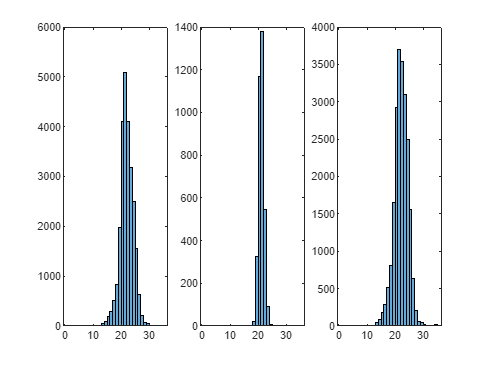


for i = 2:size(spikedata,1)
    spike_interval_temp(i-1,1) = spikedata(i,1) - spikedata(i-1,1);
end

edge           = [500 100 35]; 
edges1         = 1:edge(1); 
edges2         = 1:edge(2); 
edges3         = 1:edge(3); 

% 全局interval
spike_interval = spike_interval_temp(find(spike_interval_temp>0));

% 200ms前的interval
for i = 2:size(spikedata,1)
    if spikedata(i,1)<200
        spike_interval_temp1(i-1,1) = spikedata(i,1) - spikedata(i-1,1);
    end
end
spike_interval1 = spike_interval_temp1(find(spike_interval_temp1>0));

% 200ms后的interval
for i = 2:size(spikedata,1)
    if spikedata(i,1)>200
        spike_interval_temp2(i-1,1) = spikedata(i,1) - spikedata(i-1,1);
    end
end
spike_interval2 = spike_interval_temp(find(spike_interval_temp2>0));

figure; 
subplot(1,3,1)
h1             = histogram(spike_interval,edges3);
subplot(1,3,2)
h2             = histogram(spike_interval1,edges3);
subplot(1,3,3)
h3             = histogram(spike_interval2,edges3);



spike_interval_min = mean(spike_interval)

spike_interval_min = 22.0714

## 提出（定义）一种同步性标准：discrete synchronization


Discrete_timestep = 5; % 离散间距为5ms

Discrete_tspan    = 0:Discrete_timestep:T_MAX;  

Events_matrix     = zeros(size(Discrete_tspan,2),n);

tic
for i = 1:n
    spike_time_temp  =  spiketime2(Vmembrane(:,i), tspan);
    for j = 1:length(spike_time_temp)
        Discrete_ord                  = spike_time_temp(j,1)/Discrete_timestep;
        Discrete_ord                  = ceil(Discrete_ord);
        Events_matrix(Discrete_ord,i) = Events_matrix(Discrete_ord,i)+1; 
    end
end
toc

历时 0.036048 秒。


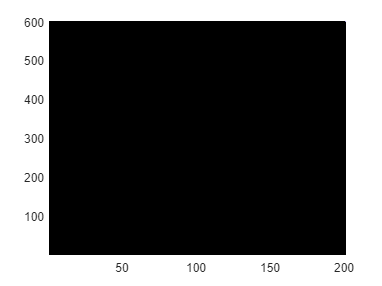


figure;
pcolor(Events_matrix'); 

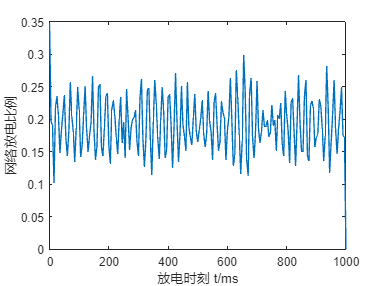

% shading flat

% k = zeros(n,n);
% for i = 1:size(Events_matrix,2)      % number of neuron
%     for j = 1:size(Events_matrix,1)  % number of discrete spacings
%         if  ~(all(Events_matrix(:,i) == 0) || all(Events_matrix(:,j) == 0))
%             k_ij = sum(Events_matrix(:,i) .* Events_matrix(:,j)) / sqrt(sum(Events_matrix(:,i)) * sum(Events_matrix(:,j)));
%             k(i,j) = k_ij;
%         end
%     end
% end

spiking_ratio = zeros(size(Events_matrix,1),1);
for i = 1:size(Events_matrix,1)          % number of discrete spacings
    for j = 1:size(Events_matrix,2)      % number of neuron
        if Events_matrix(i,j) > 0
            spiking_ratio(i,1) = spiking_ratio(i,1) + Events_matrix(i,j);
        end
    end
end

% for i = 1:size(Events_matrix,1)
%     spiking_ratio(i,1) = sum(Events_matrix(i,:));
% end

spiking_ratio = spiking_ratio./n;

figure;
plot(Discrete_tspan,spiking_ratio); 
xlabel('放电时刻 t/ms');
ylabel('网络放电比例');

## 计算结果的sychronization值

synchro = synchronization(Vmembrane,n,tspan)

synchro = 0.0731

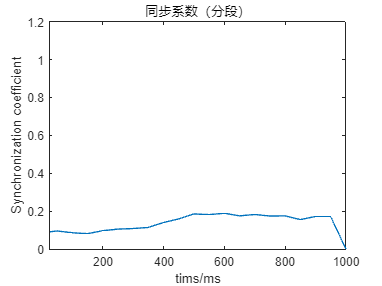


ITVL = 50;
sync_coefficients = synchronization_interval(Vmembrane, n, tspan, ITVL);
% 
num_ITVL = floor(tspan(end) / ITVL); % 计算可划分的区间数
ITVL_tspan = linspace(tspan(1), tspan(end), num_ITVL+1);
figure;
plot(ITVL_tspan, sync_coefficients)
title('同步系数（分段）')
axis([25 1000 0 1.2])
xlabel('tims/ms')
ylabel('Synchronization coefficient')

## 绘制所有神经元的放电率变化图

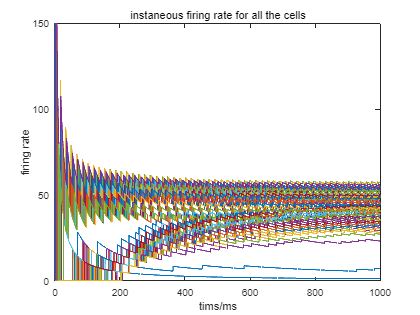


tic
figure;
% parfor
for j = 1:n
    ins_firing_rate(:,j) = countspikes2(Vmembrane(:,j), tspan); 
    plot(tspan,ins_firing_rate(:,j)); 
    hold on
end
title('instaneous firing rate for all the cells')
axis([0 T_MAX 0 150]); 
xlabel('tims/ms')
ylabel('firing rate')

toc

历时 18.972182 秒。


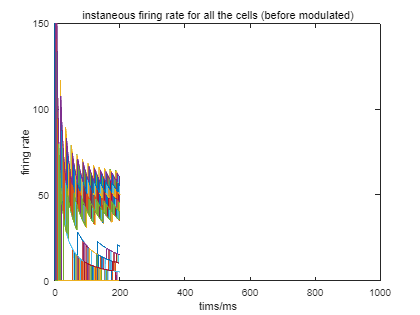


% 分别绘制0-200ms和200-1000ms的放电率变化图
% before 200ms
tic
figure;
% parfor
for j = 1:n
    ins_firing_rate_(:,j) = countspikes2(Vmembrane(1:2000,j), tspan(1:2000)); 
    plot(tspan(1:2000),ins_firing_rate_(:,j)); 
    hold on
end
title('instaneous firing rate for all the cells (before modulated)')
axis([0 T_MAX 0 150]); 
xlabel('tims/ms')
ylabel('firing rate')

toc

历时 1.000018 秒。


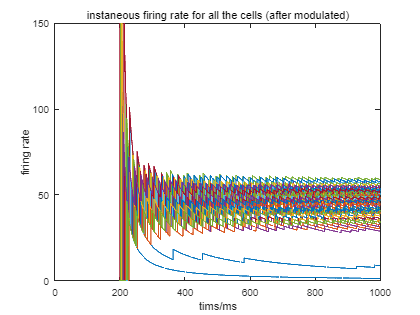


% after 200ms
tic
figure;
% parfor
for j = 1:n
    ins_firing_rate__(:,j) = countspikes2(Vmembrane(2001:10001,j), tspan(2001:10001)); 
    plot(tspan(2001:10001),ins_firing_rate__(:,j));
    hold on
end
title('instaneous firing rate for all the cells (after modulated)')
axis([0 T_MAX 0 150]); 
xlabel('tims/ms') 
ylabel('firing rate')

toc

历时 14.192125 秒。


## 绘制所有神经元的spiking counting图

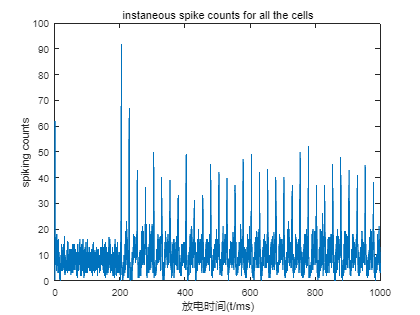


ins_spike_count = zeros(length(Vmembrane),1);
for j = 1:n
    thresholdSpikes = Vmembrane(:,j)>-10;
    ins_spike_count = ins_spike_count + double(thresholdSpikes);
end
figure;
plot(tspan,ins_spike_count);
title('instaneous spike counts for all the cells')
axis([0 T_MAX 0 100])
xlabel('放电时间(t/ms)')
ylabel('spiking counts')

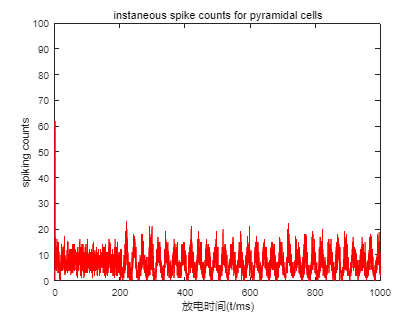


ins_spike_count_pyramidal = zeros(length(Vmembrane),1);
jj = find(type_of_neuron == 1);
for j = 1:size(jj,1)
    thresholdSpikes_pyramidal = Vmembrane(:,jj(j))>-10;
    ins_spike_count_pyramidal = ins_spike_count_pyramidal + double(thresholdSpikes_pyramidal);
end
figure;
plot(tspan,ins_spike_count_pyramidal,'red');
title('instaneous spike counts for pyramidal cells')
axis([0 T_MAX 0 100])
xlabel('放电时间(t/ms)')
ylabel('spiking counts')

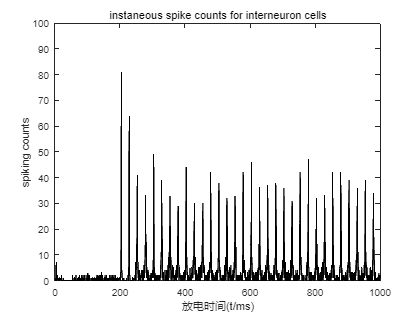


ins_spike_count_interneuron = zeros(length(Vmembrane),1);
jj = find(type_of_neuron == 2);
for j = 1:size(jj,1)
    thresholdSpikes_interneuron = Vmembrane(:,jj(j))>-10;
    ins_spike_count_interneuron = ins_spike_count_interneuron + double(thresholdSpikes_interneuron);
end
figure;
plot(tspan,ins_spike_count_interneuron,'black');
title('instaneous spike counts for interneuron cells')
axis([0 T_MAX 0 100])
xlabel('放电时间(t/ms)')
ylabel('spiking counts')

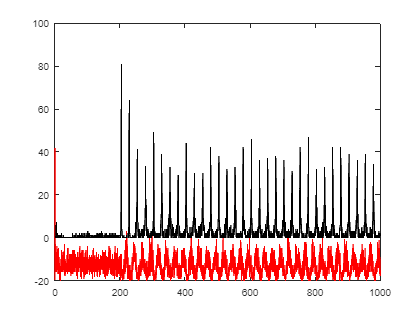


figure;
plot(tspan,ins_spike_count_pyramidal-20,'red');
hold on
plot(tspan,ins_spike_count_interneuron,'black');

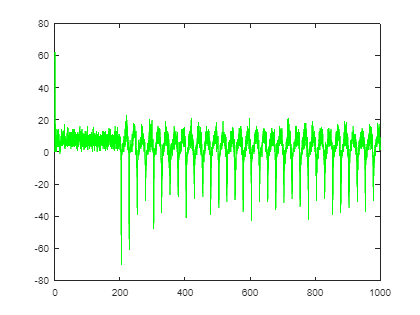


figure;
plot(tspan,ins_spike_count_pyramidal - ins_spike_count_interneuron,'green');

mean(ins_spike_count_pyramidal - ins_spike_count_interneuron)

ans = 3.4443

## 结果输出(raster plots and spike count)

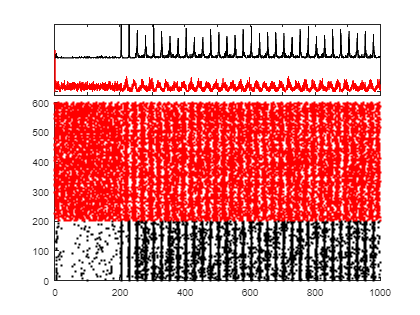

figure;
subplot(10,1,[1 2 3])
plot(tspan,ins_spike_count_pyramidal-50,'red');
hold on
plot(tspan,ins_spike_count_interneuron,'black');
% title('instaneous spike counts for all the cells')
axis([0 T_MAX -55 50])
% xlabel('放电时间(t/ms)')
% ylabel('spiking counts')
set(gca,'YTickLabel',[])
set(gca,'XTickLabel',[])  % 拉长后图长30.5cm是记录的标准尺寸

subplot(10,1,[4 5 6 7 8 9 10])
type = spikedata1(:,3); 
colors = zeros(size(type));
colors(type == 1) = 1;   % pyramidal blue
colors(type == 2) = 2;   % interneuron red
scatter(spikedata1(:,1), spikedata1(:,2), 5, colors, 'filled');
colormap ([1 0 0; 0 0 0]);   % E-红色 I-黑色 
title('')
% xlabel('放电时刻 t/ms');
% ylabel('神经元序号');
% xlabel('time/ms');
% ylabel('Neuron Index');
xmin = 0;
xmax = max(tspan);
ymin = 0;
ymax = n;
axis([xmin xmax ymin ymax]);

% set(gca,'YTickLabel',[])
% set(gca,'XTickLabel',[])


## 绘制结果输出图

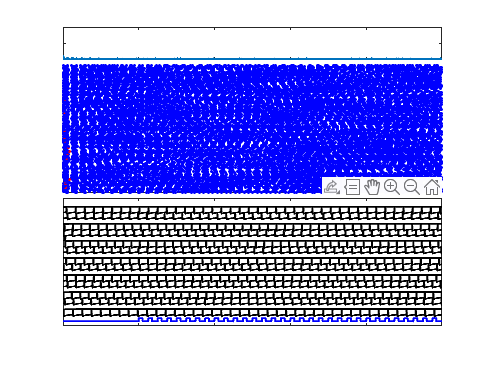

figure;

subplot(16,1,[1 2])
plot(tspan,ins_spike_count,'linewidth',2);
% title('instaneous spike counts for all the cells')
axis([0 T_MAX 0 400])
% xlabel('放电时间(t/ms)')
% ylabel('spiking counts')
set(gca,'YTickLabel',[])
set(gca,'XTickLabel',[])

type = spikedata(:,3); 
colors = zeros(size(type));
colors(type == 1) = 1;   % pyramidal blue
colors(type == 2) = 2;   % interneuron red

% figure;
subplot(16,1,[3 4 5 6 7 8 9])
scatter(spikedata(:,1), spikedata(:,2), 5, colors, 'filled');
colormap ([0 0 1; 1 0 0]);   % 蓝色 红色
title('')
% xlabel('放电时刻 t/ms');
% ylabel('神经元序号');
% xlabel('time/ms');
% ylabel('Neuron Index');
xmin = 0;
xmax = max(tspan);
ymin = 0;
ymax = n;
axis([xmin xmax ymin ymax]);
set(gca,'YTickLabel',[])
set(gca,'XTickLabel',[])

% hobj=gca;
% set(hobj.XAxis,'Visible','on')
% set(hobj.YAxis,'Visible','on')

% figure;
subplot(16,1,[10 11 12 13 14 15 16])
plot(tspan,Vmembrane(:,1),'black','linewidth',1.5); 
hold on
for i = 2:20
    plot(tspan,Vmembrane(:,i)-140*(i-1),'black','linewidth',1.5);
end
% plot(tspan,(optoStimulus_in.*70-80),'cyan');
plot(tspan,(optoStimulus_in.*70+70-2950),'blue','linewidth',1.5);
% xlabel('time/ms')
axis([0 1000 -3000 150])
set(gca,'YTick',[])
set(gca,'XTickLabel',[])

## 绘制所有神经元的平均放电率 - 直方图

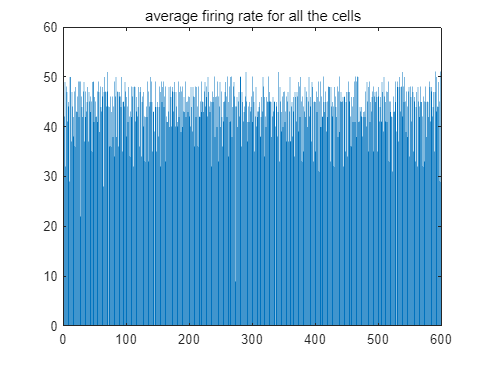


figure;
bar(1:n,ins_firing_rate(end,:)); 
title('average firing rate for all the cells')

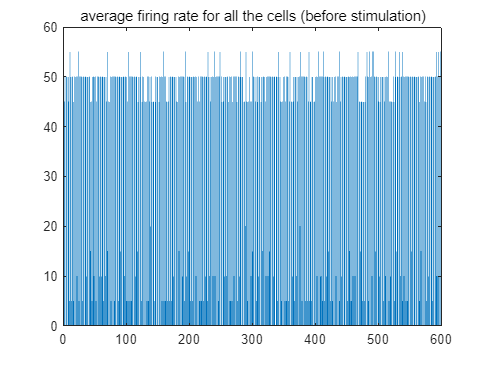


figure;
bar(1:n,ins_firing_rate_(end,:)); 
title('average firing rate for all the cells (before stimulation)')

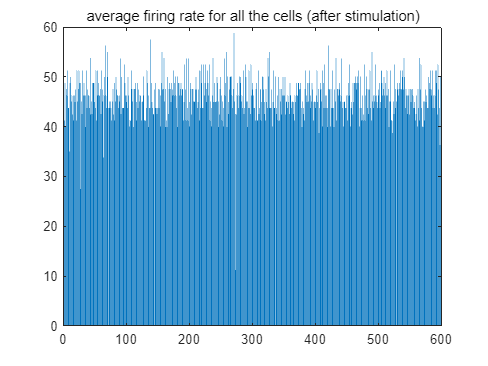


figure;
bar(1:n,ins_firing_rate__(end,:)); 
title('average firing rate for all the cells (after stimulation)')

## 绘制e和i神经元的平均放电率 - 随时间变化

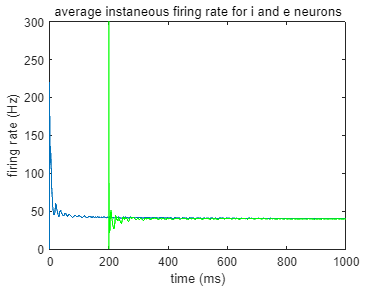

% Global 
ins_firing_rate_i = zeros(length(tspan),1);
ins_firing_rate_e = zeros(length(tspan),1);

for i = 1:100
    ins_firing_rate_i = ins_firing_rate_i + ins_firing_rate(:,i);
end

% for i = 11:110
%     ins_firing_rate_e = ins_firing_rate_e + ins_firing_rate(:,i);
% end

ins_firing_rate_i = ins_firing_rate_i ./100;
% ins_firing_rate_e = ins_firing_rate_e ./100;

% After stimulation
ins_firing_rate_i_ = zeros(length(ins_firing_rate__),1);
% ins_firing_rate_e_ = zeros(length(ins_firing_rate__),1);

for i = 1:100
    ins_firing_rate_i_ = ins_firing_rate_i_ + ins_firing_rate__(:,i);
end

% for i = 11:110
%     ins_firing_rate_e_ = ins_firing_rate_e_ + ins_firing_rate__(:,i);
% end

ins_firing_rate_i_ = ins_firing_rate_i_ ./100;
% ins_firing_rate_e_ = ins_firing_rate_e_ ./100;

figure; 
plot(tspan,ins_firing_rate_i);
% hold on
% plot(tspan,ins_firing_rate_e,'red');

hold on

plot(tspan(2001:10001),ins_firing_rate_i_, 'green');
hold on
% plot(tspan(2001:10001),ins_firing_rate_e_, 'cyan');
% axis([0 T_MAX 0 150])

title('average instaneous firing rate for i and e neurons')
xlabel('time (ms)')
ylabel('firing rate (Hz)')

## 功率谱密度1

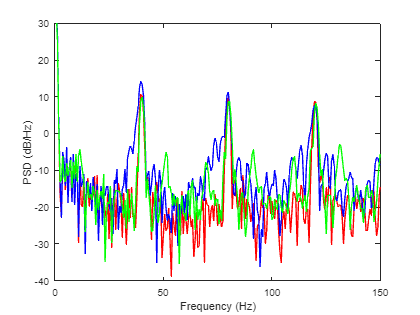


fs = 10001;
[pxx,f]=pwelch(Vmembrane(:,1),hamming(length(tspan)),[],[],fs);
figure;
plot(f,pow2db(pxx),'r')
axis([0 150 -40 30])
xlabel('Frequency (Hz)')
ylabel('PSD (dB/Hz)')
hold on
[pxx,f]=pwelch(Vmembrane(:,5),hamming(length(tspan)),[],[],fs);
plot(f,pow2db(pxx),'b')
hold on
[pxx,f]=pwelch(Vmembrane(:,40),hamming(length(tspan)),[],[],fs);
plot(f,pow2db(pxx),'g')

## 功率谱密度2

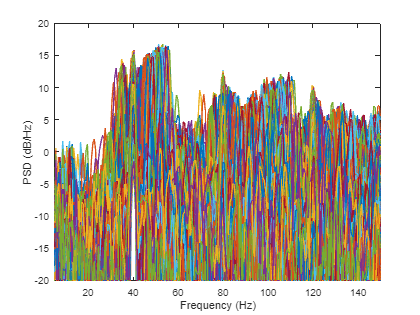

tic
fs = 10001;
figure;

[pxx,f]=pwelch(Vmembrane(:,1),hamming(length(tspan)),[],[],fs);
pxx_tt = pxx;
plot(f,pow2db(pxx))
hold on

for i = 2:n
    [pxx,f]=pwelch(Vmembrane(:,i),hamming(length(tspan)),[],[],fs);
    pxx_tt = pxx_tt+pxx;
    plot(f,pow2db(pxx))
    hold on
end
axis([5 150 -20 20])
xlabel('Frequency (Hz)')
ylabel('PSD (dB/Hz)')

toc

历时 2.985219 秒。


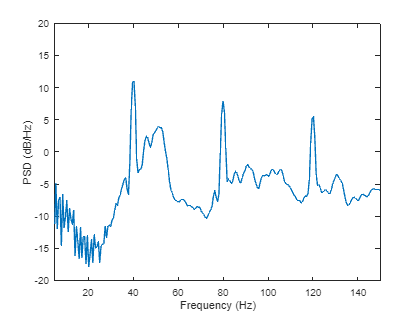


figure;
plot(f,pow2db(pxx_tt./n));
axis([5 150 -20 20])
xlabel('Frequency (Hz)')
ylabel('PSD (dB/Hz)')


pxx_tt_dB = pow2db(pxx_tt./n);


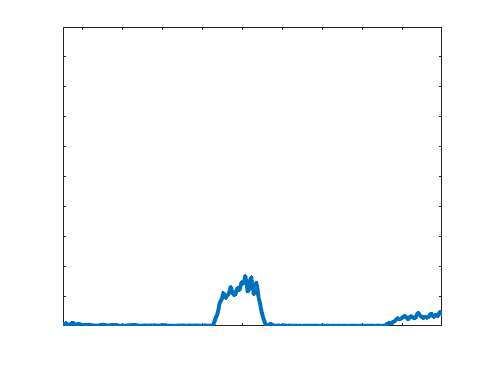

figure;
plot(f,10.^(log10(pxx_tt)),'linewidth',3);
axis([10 200 0 20000])
% xlabel('Frequency (Hz)')
% ylabel('PSD (dB/Hz)')
set(gca,'YTickLabel',[])
set(gca,'XTickLabel',[])
set(gca,'YTickLabel',[])

## 功率谱密度3

tic
fs = 10001;
figure;
[pxx,f]=pwelch(sum(Vmembrane(:,1:n))./n,hamming(length(tspan)),[],[],fs);

错误使用 signal.internal.spectral.welchparse>segment_info
段的长度不能大于输入信号的长度。

出错 signal.internal.spectral.welchparse (第 34 行)
[L,noverlap,win] = segment_info(M,winp,noverlap1);

出错 welch (第 57 行)
    signal.internal.spectral.welchpars

plot(f,pow2db(pxx))

axis([10 100 0 80])
xlabel('Frequency (Hz)')
ylabel('average PSD (dB/Hz)')
toc


## 观察参数（ChR2状态）

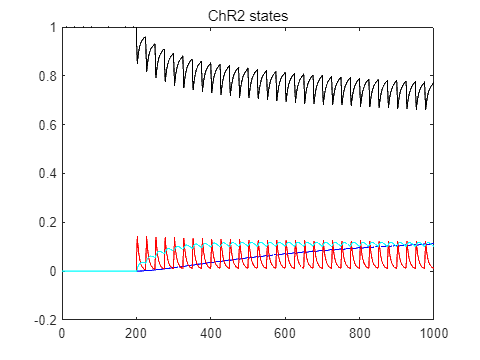


ChR2State_O1 = resultMatrix1(:,3*n+1:4*n);
ChR2State_O2 = resultMatrix1(:,4*n+1:5*n);
ChR2State_C2 = resultMatrix1(:,5*n+1:6*n);
ChR2State_C1 = 1-ChR2State_O1-ChR2State_O2-ChR2State_C2;
hNa          = resultMatrix1(:,n+1:2*n); 
nK           = resultMatrix1(:,2*n+1:3*n); 

O1O2         = ChR2State_O1+ 0.05*ChR2State_O2;         %定义O1、O2组成的等效光遗传电导

figure;
plot(tspan,ChR2State_C1,'black');
hold on
plot(tspan,ChR2State_C2,'blue');
hold on
plot(tspan,ChR2State_O1,'red');
hold on
plot(tspan,ChR2State_O2,'cyan');
title('ChR2 states')

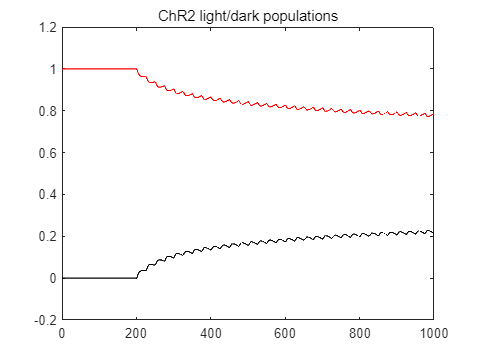


figure;
plot(tspan,ChR2State_C1+ChR2State_O1,'red');    % dark populations
hold on
plot(tspan,ChR2State_C2+ChR2State_O2,'black');  % light populations
title('ChR2 light/dark populations')

## 2D相图

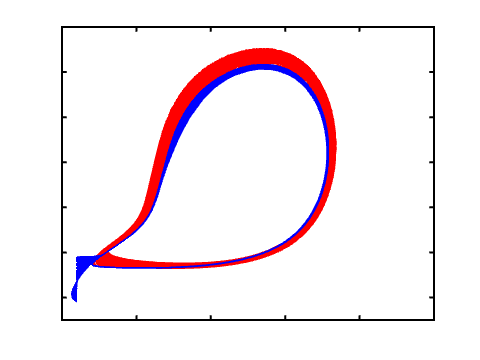

% figure;
% plot(hNa(1:2000,25),Vmembrane(1:2000,25),'black');
% figure;
% plot(hNa(2001:end,25),Vmembrane(2001:end,25),'red');
% ------------------------------------------------------
% figure;
% for i = find(type_of_neuron == 2)
%     plot(hNa(2001:end,i),Vmembrane(2001:end,i),'red');
%     hold on
% end
% for i = find(type_of_neuron == 2)
%     plot(hNa(1:2000,i),Vmembrane(1:2000,i),'blue');
%     hold on
% end
% axis([0 1 -90 40])
% set(gca,'xtick',[0 0.2 0.4 0.6 0.8 1])
% set(gca,'ytick',[-80 -60 -40 -20 0 20 40])
% ------------------------------------------------------

% figure;
% plot(nK(1:2000,25),Vmembrane(1:2000,25),'black');
% figure;
% plot(nK(2001:end,25),Vmembrane(2001:end,25),'red');
% ------------------------------------------------------
figure;
for i = find(type_of_neuron == 2)
    plot(nK(2001:end,i),Vmembrane(2001:end,i),'red');
    hold on
end
for i = find(type_of_neuron == 2)
    plot(nK(1:2000,i),Vmembrane(1:2000,i),'blue');
    hold on
end
axis([0 1 -90 40])
set(gca,'xtick',[0 0.2 0.4 0.6 0.8 1])
set(gca,'ytick',[-80 -60 -40 -20 0 20 40])
set(gca,'xticklabel',[])
set(gca,'yticklabel',[])
set(gca,'zticklabel',[])
set(gca,'Xcolor','black')
set(gca,'Ycolor','black')
set(gca,'Zcolor','black')
ax = gca;
ax.XAxis.LineWidth = 1.5;
ax.YAxis.LineWidth = 1.5;
ax.ZAxis.LineWidth = 1.5;

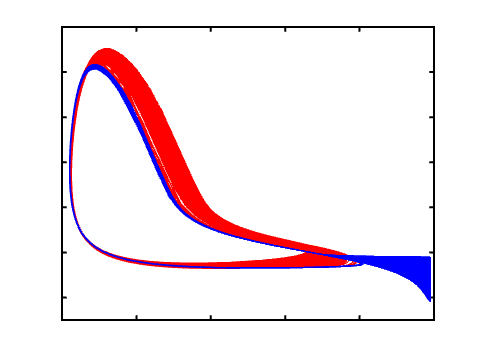

% ------------------------------------------------------

% figure;
% plot(ChR2State_O1(:,30),Vmembrane(:,30),'blue');

% figure;
% plot(O1O2(:,30),Vmembrane(:,30),'blue');
% -----------------------------------------------------
figure;
for i = find(type_of_neuron == 2)
    plot(hNa(2001:end,i),Vmembrane(2001:end,i),'red');
    hold on
end
for i = find(type_of_neuron == 2)
    plot(hNa(1:2000,i),Vmembrane(1:2000,i),'blue');
    hold on
end
axis([0 1 -90 40])
set(gca,'xtick',[0 0.2 0.4 0.6 0.8 1])
set(gca,'ytick',[-80 -60 -40 -20 0 20 40])
set(gca,'xticklabel',[])
set(gca,'yticklabel',[])
set(gca,'zticklabel',[])
set(gca,'Xcolor','black')
set(gca,'Ycolor','black')
set(gca,'Zcolor','black')
ax = gca;
ax.XAxis.LineWidth = 1.5;
ax.YAxis.LineWidth = 1.5;
ax.ZAxis.LineWidth = 1.5;

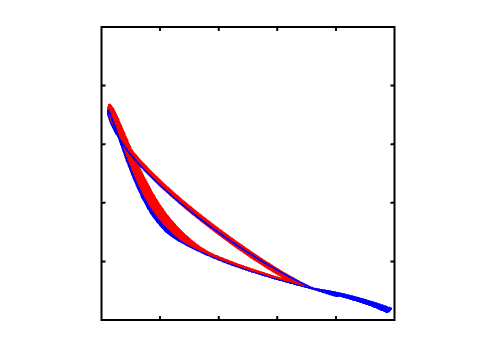

% ------------------------------------------------------

% -----------------------------------------------------
figure;
for i = find(type_of_neuron == 2)
    plot(hNa(2001:end,i),nK(2001:end,i),'red');
    hold on
end
for i = find(type_of_neuron == 2)
    plot(hNa(1:2000,i),nK(1:2000,i),'blue');
    hold on
end
set(gca,'xtick',[0 0.2 0.4 0.6 0.8 1])
set(gca,'ytick',[0 0.2 0.4 0.6 0.8 1])
axis equal
axis([0 1 0 1])
set(gca,'xticklabel',[])
set(gca,'yticklabel',[])
set(gca,'zticklabel',[])
set(gca,'Xcolor','black')
set(gca,'Ycolor','black')
set(gca,'Zcolor','black')
ax = gca;
ax.XAxis.LineWidth = 1.5;
ax.YAxis.LineWidth = 1.5;
ax.ZAxis.LineWidth = 1.5;

% ---------------------------------------------------

% figure;
% for i = 1:n
%     plot(hNa(:,i),nK(:,i),'black');
%     hold on
% end
% axis([0 1 0 1])
% 
% figure;
% plot(hNa(:,10),nK(:,10),'black');
% axis([0 1 0 1])
% 
% figure;
% for i = 1:n
%     plot(nK(:,i),O1O2(:,i),'black');
%     hold on
% end
% axis([0 1 0 1])
% 
% figure;
% plot(nK(:,10),O1O2(:,10),'black');
% axis([0 1 0 1])
% 
% 
% figure;
% for i = 1:n
%     plot(ChR2State_O1(:,i),ChR2State_O2(:,i),'black');
%     hold on
% end
% axis([0.1 0.3 0.4 0.5])
% 
% figure;
% plot(ChR2State_O1(:,25),ChR2State_O2(:,25),'black');
% axis([0.1 0.3 0.4 0.5])


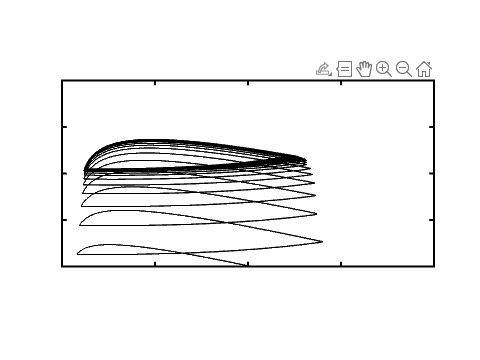


% -----------------------------------------------------
figure;
for i = find(type_of_neuron == 2)
    plot(ChR2State_O1(:,i),ChR2State_O2(:,i),'black');
    hold on
end
axis equal
axis([0 0.2 0.05 0.15])

set(gca,'xtick',0:0.05:0.2)
set(gca,'ytick',0.05:0.025:0.15)
set(gca,'xticklabel',[])
set(gca,'yticklabel',[])
set(gca,'zticklabel',[])
set(gca,'Xcolor','black')
set(gca,'Ycolor','black')
set(gca,'Zcolor','black')
ax = gca;
ax.XAxis.LineWidth = 1.5;
ax.YAxis.LineWidth = 1.5;
ax.ZAxis.LineWidth = 1.5;

% ------------------------------------------------------


## 绘制3D Portraits

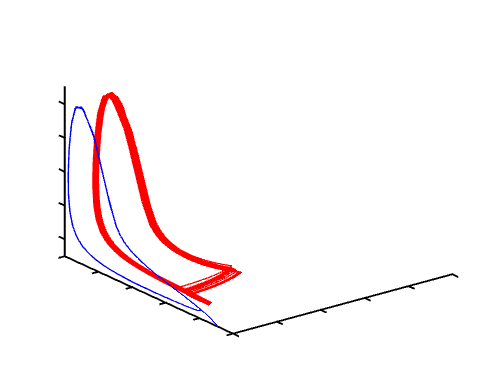

% figure;
% for i = 1:n
%     plot3(O1O2(:,i),1-hNa(:,i),Vmembrane(:,i),'blue');
%     hold on
% end
% axis([0 0.5 0 1 -70 30])
% camorbit(25,40);

% figure;
% for i = 1:n
%     plot3(hNa(:,i),nK(:,i),O1O2(:,i),'black');
%     hold on
% end
% axis([0 1 0 1 0 0.3])
% camorbit(0,45);

% figure;
% for i = 1:n
%     plot3(hNa(:,i),O1O2(:,i),Vmembrane(:,i),'black');
%     hold on
% end
% axis([0 1 0 0.3 -70 30])
% camorbit(0,45);
figure;
plot3(O1O2(1:2000,100),1-hNa(1:2000,100),Vmembrane(1:2000,100),'blue','LineWidth',0.5);
hold on
plot3(O1O2(2001:end,100),1-hNa(2001:end,100),Vmembrane(2001:end,100),'red','LineWidth',0.5);
axis([0 0.5 0 1 -70 30])
set(gca,'xtick',[0 0.1 0.2 0.3 0.4 0.5])
set(gca,'ytick',[0 0.2 0.4 0.6 0.8 1])
set(gca,'ztick',[-60 -40 -20 0 20])
set(gca,'xticklabel',[])
set(gca,'yticklabel',[])
set(gca,'zticklabel',[])
set(gca,'Xcolor','black')
set(gca,'Ycolor','black')
set(gca,'Zcolor','black')
ax = gca;
ax.XAxis.LineWidth = 1.5;
ax.YAxis.LineWidth = 1.5;
ax.ZAxis.LineWidth = 1.5;

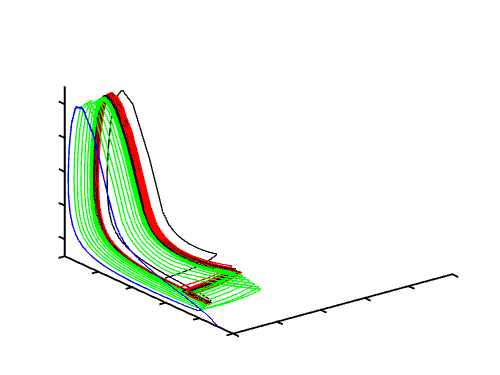


% ax = gca;
% ax.Line.Color = 'black';
% ax.XTick = 'off';

figure;
plot3(O1O2(1:2000,100),1-hNa(1:2000,100),Vmembrane(1:2000,100),'blue','LineWidth',0.5);
hold on
plot3(O1O2(2001:end,100),1-hNa(2001:end,100),Vmembrane(2001:end,100),'red','LineWidth',0.5);
plot3(O1O2(2001:end,200),1-hNa(2001:end,200),Vmembrane(2001:end,200),'green','LineWidth',0.5);
plot3(O1O2(2001:end,300),1-hNa(2001:end,300),Vmembrane(2001:end,300),'black','LineWidth',0.5);

axis([0 0.5 0 1 -70 30])
set(gca,'xtick',[0 0.1 0.2 0.3 0.4 0.5])
set(gca,'ytick',[0 0.2 0.4 0.6 0.8 1])
set(gca,'ztick',[-60 -40 -20 0 20])
set(gca,'xticklabel',[])
set(gca,'yticklabel',[])
set(gca,'zticklabel',[])
set(gca,'Xcolor','black')
set(gca,'Ycolor','black')
set(gca,'Zcolor','black')
ax = gca;
ax.XAxis.LineWidth = 1.5;
ax.YAxis.LineWidth = 1.5;
ax.ZAxis.LineWidth = 1.5;


% figure;
% plot3(nK(1:2000,100),O1O2(1:2000,100),Vmembrane(1:2000,100),'black');
% hold on
% plot3(nK(2001:end,100),O1O2(2001:end,100),Vmembrane(2001:end,100),'red');

% O1O2_array = O1O2(:,1);
% hNa_array  = hNa(:,1);
% nK_array   = nK(:,1);
% for j = 2:400
%     O1O2_array = [O1O2_array;O1O2(:,j)];
%     hNa_array  = [hNa_array;hNa(:,j)];
%     nK_array   = [nK_array;nK(:,j)];
% end

% figure;
% plot3(hNa_array,nK_array,O1O2_array,'black');
% axis([0 1 0 1 0 1])
% 
% figure;
% plot(hNa_array,nK_array);
% axis([0 1 0 1])

## 观察突触

synapse = resultMatrix1(:,6*n+1:end);
figure;
for i = 1:200
    subplot(20,10,i)
    plot(tspan,synapse(:,i));
end


% function compressedMatrix = sparseToCompressed(sparseMatrix)
%     [row, col, val] = find(sparseMatrix);
%     numNonZeros = nnz(sparseMatrix);  % 非零矩阵元素的数目
%     numRows = size(sparseMatrix, 1); % 行数目
%     
%     compressedMatrix = zeros(numNonZeros,3);
%     compressedMatrix(:, 1) = row;
%     compressedMatrix(:, 2) = col;
%     compressedMatrix(:, 3) = val;
% end
% 
% function sparseMatrix = compressedToSparse(compressedMatrix)
%     numRows = max(compressedMatrix(:,1));
%     numCols = max(compressedMatrix(:,2));
%     numNonZeros = size(compressedMatrix,1); 
%     compressedData = compressedMatrix(:,3);
%     
%     row = compressedMatrix(1:numNonZeros);
%     col = compressedMatrix(numNonZeros+1:2*numNonZeros);
%     val = compressedMatrix(2*numNonZeros+1:end);
%     
%     sparseMatrix = sparse(row, col, val, numRows, numCols);
% end


% function spike_time = spiketime(Vmembrane,tspan)
%     step = tspan(2) - tspan(1);
%     threshold = -1;
%     thresholdSpikes = zeros(length(Vmembrane),1);
% %     spike_time = zeros(length(Vmembrane),1);
%     onfiring = find(Vmembrane > threshold);
%     for i = 2:length(onfiring)-1
%         if Vmembrane(onfiring(i),1) >= Vmembrane(onfiring(i)-1,1) && Vmembrane(onfiring(i),1) >= Vmembrane(onfiring(i)+1,1)
%             thresholdSpikes(onfiring(i),1)=1;
%         end
%     end
%     detectedSpikes = thresholdSpikes;
%     index=find(detectedSpikes);
%     % spike_time = round(index*step);   % 获取放电时刻
%     spike_time = index*step;
% end